# Clase 5

syms Tij(x_i_j,y_i_j,z_i_j,gi_j,bi_j,ai_j)

% Homogeneous transform
Tij(x_i_j,y_i_j,z_i_j,gi_j,bi_j,ai_j) = [cos(ai_j)*cos(bi_j) cos(ai_j)*sin(bi_j)*sin(gi_j)-sin(ai_j)*cos(gi_j) sin(ai_j)*sin(gi_j)+cos(ai_j)*sin(bi_j)*cos(gi_j) x_i_j; sin(ai_j)*cos(bi_j) cos(ai_j)*cos(gi_j)+sin(ai_j)*sin(bi_j)*sin(gi_j) sin(ai_j)*sin(bi_j)*cos(gi_j)-cos(ai_j)*sin(gi_j) y_i_j; -sin(bi_j) cos(bi_j)*sin(gi_j) cos(bi_j)*cos(gi_j) z_i_j; 0 0 0 1]

$$Tij(x\_i\_j, y\_i\_j, z\_i\_j, gi\_j, bi\_j, ai\_j) = \left(\begin{array}{cccc} \cos\left({\mathrm{ai}}_{j}\right)\,\cos\left({\mathrm{bi}}_{j}\right) & \cos\left({\mathrm{ai}}_{j}\right)\,\sin\left({\mathrm{bi}}_{j}\right)\,\sin\left({\mathrm{gi}}_{j}\right)-\cos\left({\mathrm{gi}}_{j}\right)\,\sin\left({\mathrm{ai}}_{j}\right) & \sin\left({\mathrm{ai}}_{j}\right)\,\sin\left({\mathrm{gi}}_{j}\right)+\cos\left({\mathrm{ai}}_{j}\right)\,\cos\left({\mathrm{gi}}_{j}\right)\,\sin\left({\mathrm{bi}}_{j}\right) & x_{i,j}\\ \cos\left({\mathrm{bi}}_{j}\right)\,\sin\left({\mathrm{ai}}_{j}\right) & \cos\left({\mathrm{ai}}_{j}\right)\,\cos\left({\mathrm{gi}}_{j}\right)+\sin\left({\mathrm{ai}}_{j}\right)\,\sin\left({\mathrm{bi}}_{j}\right)\,\sin\left({\mathrm{gi}}_{j}\right) & \cos\left({\mathrm{gi}}_{j}\right)\,\sin\left({\mathrm{ai}}_{j}\right)\,\sin\left({\mathrm{bi}}_{j}\right)-\cos\left({\mathrm{ai}}_{j}\right)\,\sin\left({\mathrm{gi}}_{j}\right) & y_{i,j}\\ -\sin\left({\mathrm{bi}}_{j}\right) & \cos\left({\mathrm{bi}}_{j}\right)\,\sin\left({\mathrm{gi}}_{j}\right) & \cos\left({\mathrm{bi}}_{j}\right)\,\cos\left({\mathrm{gi}}_{j}\right) & z_{i,j}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

Modelado del elementos

Planteamiento

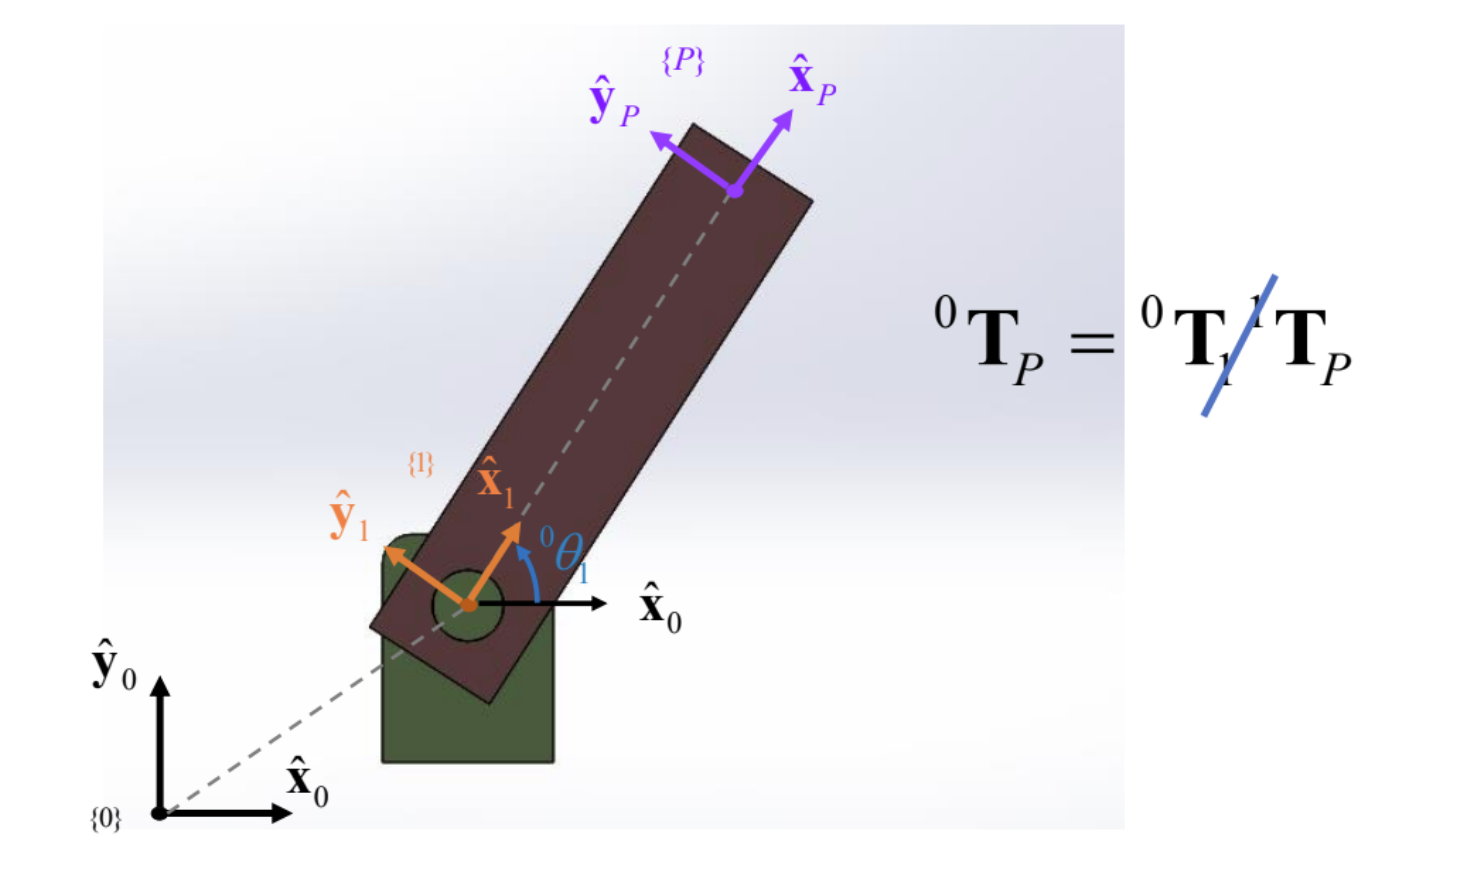

% Calculo de las transformaciones
syms x_O_1 y_O_1 theta_O_1 x_1_P

T_O_1 = Tij(x_O_1,y_O_1,0,0,0,theta_O_1)

$$T\_O\_1 = \left(\begin{array}{cccc} \cos\left(\theta_{O,1}\right) & -\sin\left(\theta_{O,1}\right) & 0 & x_{O,1}\\ \sin\left(\theta_{O,1}\right) & \cos\left(\theta_{O,1}\right) & 0 & y_{O,1}\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$


T_1_P = Tij(x_1_P,0,0,0,0,0)

$$T\_1\_P = \left(\begin{array}{cccc} 1 & 0 & 0 & x_{1,P}\\ 0 & 1 & 0 & 0\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$


T_O_P = T_O_1*T_1_P

$$T\_O\_P = \left(\begin{array}{cccc} \cos\left(\theta_{O,1}\right) & -\sin\left(\theta_{O,1}\right) & 0 & x_{O,1}+x_{1,P}\,\cos\left(\theta_{O,1}\right)\\ \sin\left(\theta_{O,1}\right) & \cos\left(\theta_{O,1}\right) & 0 & y_{O,1}+x_{1,P}\,\sin\left(\theta_{O,1}\right)\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

Definción del vector de pose 

syms xi_O_P x_O_P y_O_P theta_O_P

xi_O_P

$$xi\_O\_P = \xi_{O,P}$$

xi_O_P = [x_O_P; y_O_P; theta_O_P]

$$xi\_O\_P = \left(\begin{array}{c} x_{O,P}\\ y_{O,P}\\ \theta_{O,P} \end{array}\right)$$

Definición del vector de postura


xi_O_P_q =[T_O_P(1,4);T_O_P(2,4);theta_O_1]

$$xi\_O\_P\_q = \left(\begin{array}{c} x_{O,1}+x_{1,P}\,\cos\left(\theta_{O,1}\right)\\ y_{O,1}+x_{1,P}\,\sin\left(\theta_{O,1}\right)\\ \theta_{O,1} \end{array}\right)$$

Planteamiento del modelo cinemático directo de la postura


$$\left(\begin{array}{c}
x_{O,P} \\
y_{O,P} \\
\theta_{O,P} 
\end{array}\right) = \left(\begin{array}{c}
x_{O,1} +x_{1,P} \,\cos \left(\theta_{O,1} \right)\\
y_{O,1} +x_{1,P} \,\sin \left(\theta_{O,1} \right)\\
\theta_{O,1} 
\end{array}\right)$$


Planteamiento del modelo cinemático 

modelo cinemático directo

syms x_dot_O_P y_dot_O_P theta_dot_O_P theta_dot_O_1

xi_dot_O_P = diff(xi_O_P,x_O_P)*x_dot_O_P + diff(xi_O_P,y_O_P)*y_dot_O_P + diff(xi_O_P,theta_O_P)*theta_dot_O_P

$$xi\_dot\_O\_P = \left(\begin{array}{c} {\dot{x}}_{O,P}\\ {\dot{y}}_{O,P}\\ {\dot{\theta }}_{O,P} \end{array}\right)$$

xi_dot_O_P_q = diff(xi_O_P_q,theta_O_1)*theta_dot_O_1

$$xi\_dot\_O\_P\_q = \left(\begin{array}{c} -{\dot{\theta }}_{O,1}\,x_{1,P}\,\sin\left(\theta_{O,1}\right)\\ {\dot{\theta }}_{O,1}\,x_{1,P}\,\cos\left(\theta_{O,1}\right)\\ {\dot{\theta }}_{O,1} \end{array}\right)$$

Cálculo de las aceleraciones del eslabón

syms x_dot_1_P y_dot_1_P theta_dot_1_P x_ddot_1_P y_ddot_1_P theta_ddot_1_P theta_ddot_O_1

%vector de velocidad
xi_dot_O_P = [x_dot_1_P; y_dot_1_P;theta_dot_1_P]

$$xi\_dot\_O\_P = \left(\begin{array}{c} {\dot{x}}_{1,P}\\ {\dot{y}}_{1,P}\\ {\dot{\theta }}_{1,P} \end{array}\right)$$


%vector de aceleracion
xi_ddot_O_P = [x_ddot_1_P; y_ddot_1_P;theta_ddot_1_P]

$$xi\_ddot\_O\_P = \left(\begin{array}{c} {\ddot{x}}_{1,P}\\ {\ddot{y}}_{1,P}\\ {\ddot{\theta }}_{1,P} \end{array}\right)$$




%calulo de las velocidades


xi_ddot_O_P_q = diff(xi_dot_O_P_q, theta_O_1)*theta_dot_O_1 + diff(xi_dot_O_P_q, theta_dot_O_1)*theta_ddot_O_1

$$xi\_ddot\_O\_P\_q = \left(\begin{array}{c} -x_{1,P}\,\cos\left(\theta_{O,1}\right)\,{{\dot{\theta }}_{O,1}}^{2}-{\ddot{\theta }}_{O,1}\,x_{1,P}\,\sin\left(\theta_{O,1}\right)\\ {\ddot{\theta }}_{O,1}\,x_{1,P}\,\cos\left(\theta_{O,1}\right)-{{\dot{\theta }}_{O,1}}^{2}\,x_{1,P}\,\sin\left(\theta_{O,1}\right)\\ {\ddot{\theta }}_{O,1} \end{array}\right)$$

Calculo de la dinámica

syms m_1  x_1_C1

g_O = [0;-g;0]

$$g\_O = \left(\begin{array}{c} 0\\ -g\\ 0 \end{array}\right)$$


W_O = m_1*g_O

$$W\_O = \left(\begin{array}{c} 0\\ -g\,m_{1}\\ 0 \end{array}\right)$$


R_O_1 = [T_O_1(1,1),T_O_1(1,2),T_O_1(1,3);T_O_1( ...
    2,1),T_O_1(2,2),T_O_1(2,3);T_O_1(3,1),T_O_1( ...
    3,2),T_O_1(3,3)];

R_1_O = transpose(R_O_1);

W_1 = R_1_O*W_O

$$W\_1 = \left(\begin{array}{c} -g\,m_{1}\,\sin\left(\theta_{O,1}\right)\\ -g\,m_{1}\,\cos\left(\theta_{O,1}\right)\\ 0 \end{array}\right)$$


% definicion de la acelacion del centro de masa, visto desde el sistema {O}
a_0_C1 = subs([xi_ddot_O_P_q(1);xi_ddot_O_P_q(2); 0],x_1_P,x_1_C1)

$$a\_0\_C1 = \left(\begin{array}{c} -x_{1,\mathrm{C1}}\,\cos\left(\theta_{O,1}\right)\,{{\dot{\theta }}_{O,1}}^{2}-{\ddot{\theta }}_{O,1}\,x_{1,\mathrm{C1}}\,\sin\left(\theta_{O,1}\right)\\ {\ddot{\theta }}_{O,1}\,x_{1,\mathrm{C1}}\,\cos\left(\theta_{O,1}\right)-{{\dot{\theta }}_{O,1}}^{2}\,x_{1,\mathrm{C1}}\,\sin\left(\theta_{O,1}\right)\\ 0 \end{array}\right)$$

% la aceleacion del centro de masa vista desde el sistema {1}
a_1_C1 = simplify(R_1_O*a_0_C1)

$$a\_1\_C1 = \left(\begin{array}{c} -{{\dot{\theta }}_{O,1}}^{2}\,x_{1,\mathrm{C1}}\\ {\ddot{\theta }}_{O,1}\,x_{1,\mathrm{C1}}\\ 0 \end{array}\right)$$


F_a_C1 = m_1*a_1_C1

$$F\_a\_C1 = \left(\begin{array}{c} -m_{1}\,{{\dot{\theta }}_{O,1}}^{2}\,x_{1,\mathrm{C1}}\\ m_{1}\,{\ddot{\theta }}_{O,1}\,x_{1,\mathrm{C1}}\\ 0 \end{array}\right)$$



% Calculo de la fuerza de reaccion

F_1_reac = -W_1 +F_a_C1

$$F\_1\_reac = \left(\begin{array}{c} g\,m_{1}\,\sin\left(\theta_{O,1}\right)-m_{1}\,{{\dot{\theta }}_{O,1}}^{2}\,x_{1,\mathrm{C1}}\\ g\,m_{1}\,\cos\left(\theta_{O,1}\right)+m_{1}\,{\ddot{\theta }}_{O,1}\,x_{1,\mathrm{C1}}\\ 0 \end{array}\right)$$

Calculo de los momentos

syms x_1_C1

p_1_C1 = [x_1_C1; 0; 0]

$$p\_1\_C1 = \left(\begin{array}{c} x_{1,\mathrm{C1}}\\ 0\\ 0 \end{array}\right)$$


% momento con respecto al peso

N_1_W = cross(p_1_C1,W_1)

$$N\_1\_W = \left(\begin{array}{c} 0\\ 0\\ -g\,m_{1}\,x_{1,\mathrm{C1}}\,\cos\left(\theta_{O,1}\right) \end{array}\right)$$


N_1_Fac = cross(p_1_C1,F_a_C1)

$$N\_1\_Fac = \left(\begin{array}{c} 0\\ 0\\ m_{1}\,{\ddot{\theta }}_{O,1}\,{x_{1,\mathrm{C1}}}^{2} \end{array}\right)$$

syms Ixx_1 Iyy_1 Izz_1

I_C1 = [Ixx_1,0,0;0,Iyy_1,0;0,0,Izz_1]

$$I\_C1 = \left(\begin{array}{ccc} {\mathrm{Ixx}}_{1} & 0 & 0\\ 0 & {\mathrm{Iyy}}_{1} & 0\\ 0 & 0 & {\mathrm{Izz}}_{1} \end{array}\right)$$


I_1_C1 = m_1*(transpose(p_1_C1)*p_1_C1*[1,0,0;0,1,0;0,0,1]+p_1_C1*transpose(p_1_C1)) + I_C1

$$I\_1\_C1 = \left(\begin{array}{ccc} 2\,m_{1}\,{x_{1,\mathrm{C1}}}^{2}+{\mathrm{Ixx}}_{1} & 0 & 0\\ 0 & m_{1}\,{x_{1,\mathrm{C1}}}^{2}+{\mathrm{Iyy}}_{1} & 0\\ 0 & 0 & m_{1}\,{x_{1,\mathrm{C1}}}^{2}+{\mathrm{Izz}}_{1} \end{array}\right)$$

omega_dot_1 = [0;0;theta_ddot_O_1]

$$omega\_dot\_1 = \left(\begin{array}{c} 0\\ 0\\ {\ddot{\theta }}_{O,1} \end{array}\right)$$


N_I_1_C1 = I_1_C1*omega_dot_1

$$N\_I\_1\_C1 = \left(\begin{array}{c} 0\\ 0\\ {\ddot{\theta }}_{O,1}\,\left(m_{1}\,{x_{1,\mathrm{C1}}}^{2}+{\mathrm{Izz}}_{1}\right) \end{array}\right)$$

% No olvidar que el traslado de la inercia ya incluye los efectos de la
% aceleración

tao_1 = simplify(N_1_W + N_1_Fac + N_I_1_C1)

$$tao\_1 = \left(\begin{array}{c} 0\\ 0\\ 2\,m_{1}\,{\ddot{\theta }}_{O,1}\,{x_{1,\mathrm{C1}}}^{2}-g\,m_{1}\,\cos\left(\theta_{O,1}\right)\,x_{1,\mathrm{C1}}+{\mathrm{Izz}}_{1}\,{\ddot{\theta }}_{O,1} \end{array}\right)$$


tao_1 = simplify(N_1_W + N_I_1_C1)

$$tao\_1 = \left(\begin{array}{c} 0\\ 0\\ {\ddot{\theta }}_{O,1}\,\left(m_{1}\,{x_{1,\mathrm{C1}}}^{2}+{\mathrm{Izz}}_{1}\right)-g\,m_{1}\,x_{1,\mathrm{C1}}\,\cos\left(\theta_{O,1}\right) \end{array}\right)$$

Calculo de la dinámica ecuaciones de Eüler-lagrange

% calculo de las energias cineticas

T_1_C1 = Tij(x_1_C1,0,0,0,0,0)

$$T\_1\_C1 = \left(\begin{array}{cccc} 1 & 0 & 0 & x_{1,\mathrm{C1}}\\ 0 & 1 & 0 & 0\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$


  T_O_C1= T_O_1*T_1_C1

$$T\_O\_C1 = \left(\begin{array}{cccc} \cos\left(\theta_{O,1}\right) & -\sin\left(\theta_{O,1}\right) & 0 & x_{O,1}+x_{1,\mathrm{C1}}\,\cos\left(\theta_{O,1}\right)\\ \sin\left(\theta_{O,1}\right) & \cos\left(\theta_{O,1}\right) & 0 & y_{O,1}+x_{1,\mathrm{C1}}\,\sin\left(\theta_{O,1}\right)\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$


p_O_C1 = [T_O_C1(1,4);T_O_C1(2,4);0]

$$p\_O\_C1 = \left(\begin{array}{c} x_{O,1}+x_{1,\mathrm{C1}}\,\cos\left(\theta_{O,1}\right)\\ y_{O,1}+x_{1,\mathrm{C1}}\,\sin\left(\theta_{O,1}\right)\\ 0 \end{array}\right)$$


v_O_C1 = diff(p_O_C1, theta_O_1)*theta_dot_O_1

$$v\_O\_C1 = \left(\begin{array}{c} -{\dot{\theta }}_{O,1}\,x_{1,\mathrm{C1}}\,\sin\left(\theta_{O,1}\right)\\ {\dot{\theta }}_{O,1}\,x_{1,\mathrm{C1}}\,\cos\left(\theta_{O,1}\right)\\ 0 \end{array}\right)$$


omega_1_1 = [0;0;theta_dot_O_1]

$$omega\_1\_1 = \left(\begin{array}{c} 0\\ 0\\ {\dot{\theta }}_{O,1} \end{array}\right)$$


k_1 = simplify(m_1/2*transpose(v_O_C1)*v_O_C1 + 1/2*transpose(omega_1_1)*I_C1*omega_1_1)

$$k\_1 = \frac{{{\dot{\theta }}_{O,1}}^{2}\,\left(m_{1}\,{x_{1,\mathrm{C1}}}^{2}+{\mathrm{Izz}}_{1}\right)}{2}$$


u_1= -m_1*transpose(g_O)*p_O_C1

$$u\_1 = g\,m_{1}\,\left(y_{O,1}+x_{1,\mathrm{C1}}\,\sin\left(\theta_{O,1}\right)\right)$$


La = k_1 - u_1

$$La = \frac{{{\dot{\theta }}_{O,1}}^{2}\,\left(m_{1}\,{x_{1,\mathrm{C1}}}^{2}+{\mathrm{Izz}}_{1}\right)}{2}-g\,m_{1}\,\left(y_{O,1}+x_{1,\mathrm{C1}}\,\sin\left(\theta_{O,1}\right)\right)$$

% Calculo par

D_1 = diff(La,theta_dot_O_1)

$$D\_1 = {\dot{\theta }}_{O,1}\,\left(m_{1}\,{x_{1,\mathrm{C1}}}^{2}+{\mathrm{Izz}}_{1}\right)$$


tao_La_1 = diff(D_1,theta_O_1)*theta_dot_O_1 + diff(D_1,theta_dot_O_1)*theta_ddot_O_1 - diff(La,theta_O_1)

$$tao\_La\_1 = {\ddot{\theta }}_{O,1}\,\left(m_{1}\,{x_{1,\mathrm{C1}}}^{2}+{\mathrm{Izz}}_{1}\right)+g\,m_{1}\,x_{1,\mathrm{C1}}\,\cos\left(\theta_{O,1}\right)$$

tao_1

$$tao\_1 = \left(\begin{array}{c} 0\\ 0\\ {\ddot{\theta }}_{O,1}\,\left(m_{1}\,{x_{1,\mathrm{C1}}}^{2}+{\mathrm{Izz}}_{1}\right)-g\,m_{1}\,x_{1,\mathrm{C1}}\,\cos\left(\theta_{O,1}\right) \end{array}\right)$$